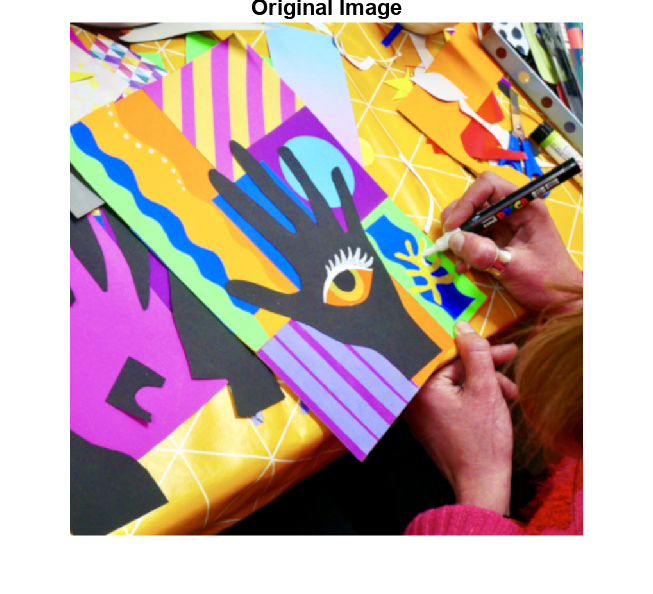

clear
clf

% Settings
partitionSize = 50;

% Load hex colors from file and put in an array
file = fileread('cormorant14.hex');
hexColors = strsplit(file, '\n');
hexColors = hexColors(~cellfun('isempty',hexColors));
rgbColors = cellfun(@(c) uint8(hex2rgb(c) * 255), hexColors, 'UniformOutput', false);
labColors = cellfun(@(c) rgb2lab(double(c) / 255), rgbColors, 'UniformOutput', false);

% Read shape image
[circle, ~, alpha] = imread('circle.png');

% Apply color to the shape and display it
% circle = colorshape(rgbColors{50}, circle);
% hImage = imshow(circle);
% set(hImage, 'AlphaData', alpha);

im = imread("hand.jpg");
[rows, cols, ~] = size(im);
modifiedIm = im;

for i = 1:partitionSize:rows
    for j = 1:partitionSize:cols
        % Define the current block's end row and column
        endRow = min(i + partitionSize - 1, rows);
        endCol = min(j + partitionSize - 1, cols);

        % Extract the current block
        currentBlock = im(i:endRow, j:endCol, :);

        % Calculate the mean color of the current block
        meanColor = mean(mean(double(currentBlock), 1), 2);



        % Convert mean color to CIELAB and
        % calculate distance between mean CIELAB and palette CIELAB ?
        % and fetch the closest color
        meanColorLab = rgb2lab(meanColor / 255);

        closestColorIndex = findClosestColor(meanColorLab, labColors);

        closestColorRgb = rgbColors{closestColorIndex};


        % Apply the mean color to the current block in the modified image
        for k = 1:3 % For each color channel
            modifiedIm(i:endRow, j:endCol, k) = closestColorRgb(k);
        end
           
    end
end

imshow(im);
title('Original Image');

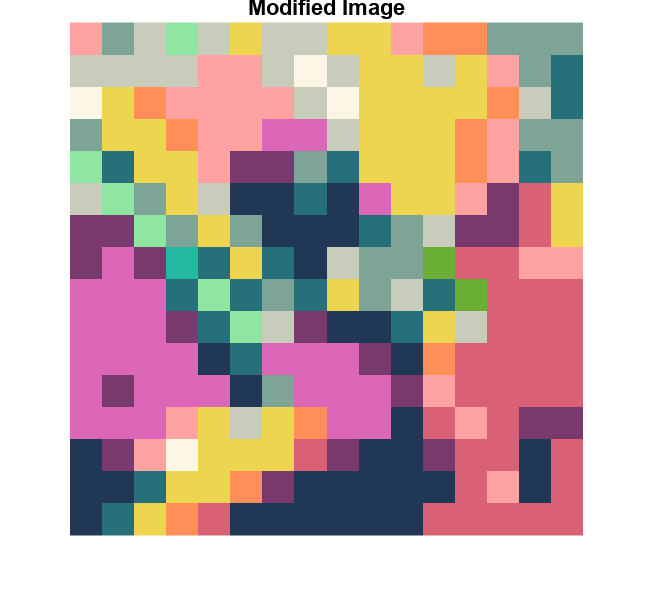


imshow(modifiedIm);
title('Modified Image');